# Demo 2 - Feature Selection Functions

## HVG analysis with single data X

cdgea; % set working directory
[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


NOTE: Genes with dropout rate > 0.95 are excluded.


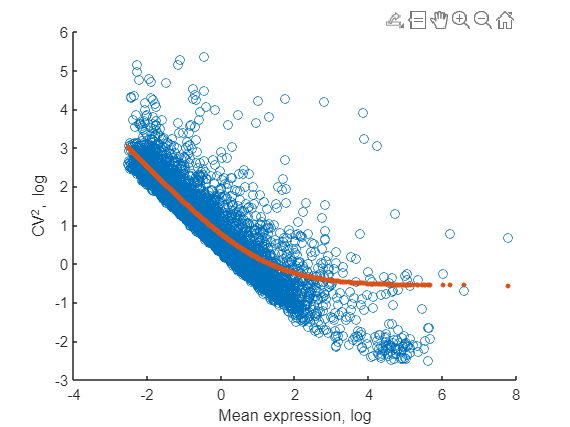

[X,genelist]=sc_selectg(X,genelist,3,1);
% Normalize data with DESeq method
Xn=sc_norm(X,'type','deseq');
[T]=sc_hvg(Xn,genelist,true,true);


% Highly variable genes (HVGenes), FDR<0.05
HVGenes=T.genes(T.fdr<0.05);
disp(HVGenes(1:10))

    "IGHG1"
    "NFATC1"
    "IGHG3"
    "IGKC"
    "IGHG4"
    "IGKV1-12"
    "SGK1"
    "WFDC2"
    "IGHM"
    "CCL22"



## Spline-fit feature selection with single data X

[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


[X,genelist]=sc_selectg(X,genelist,3,1);

sortit=true;
[T1]=sc_splinefit(X,genelist,sortit);

NOTE: Genes with dropout rate > 0.95 are excluded.


% Top 10 featured genes with highest deviation (D) values 
T1.genes(1:10)

ans = 10×1 string array
    "IGLC2"
    "IGHG1"
    "IGKC"
    "IGHG3"
    "CCL22"
    "IGHM"
    "IGHG4"
    "WFDC2"
    "IGKV1-12"
    "CCL4"


dofit=true;
showdata=true;
% Show data points and the spline-fit curve
figure;
gui.sc_scatter3genes(X,genelist,dofit,showdata);

NOTE: Genes with dropout rate > 0.95 are excluded.
scGEAToolbox controls for the variance-mean relationship of gene
expression. scGEAToolbox considers three sample statistics of each
gene: expression mean⁠, coefficient of variation⁠, and dropout rate⁠.
After normalization, it fits a spline function based on piece-wise
polynomials to model the relationship among the three statistics, 
and calculates the distance between each geneis observed statistics
to the fitted 3D spline surface. Genes with larger distances are 
ranked higher for feature selection.


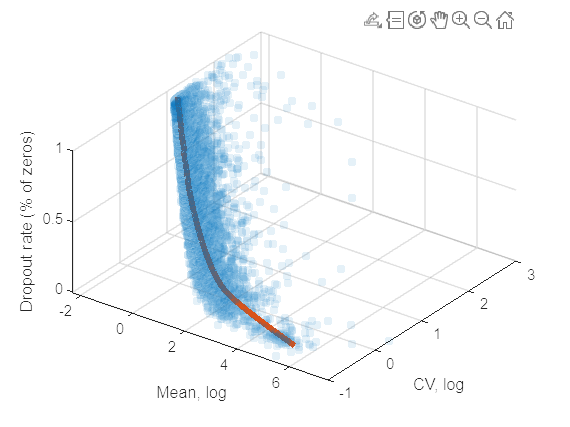

view([36.39 46.25])

## Analysis of differentially deviated (DD) genes using spline-fit feature selection with data X and Y

Read and pre-process two data sets, X and Y

[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr.csv');

Reading example_data/GSM3204304_P_P_Expr.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr.csv');

Reading example_data/GSM3204305_P_N_Expr.csv ...... done.


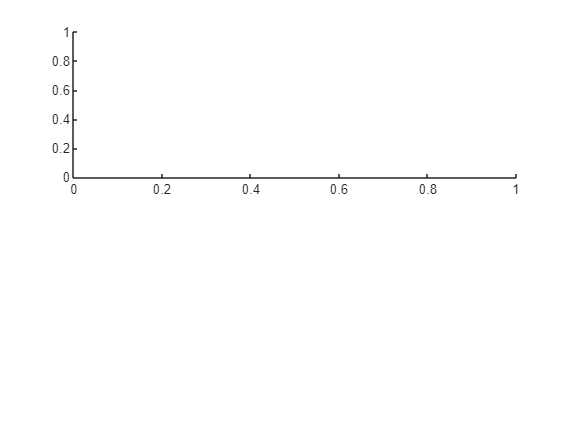

[X,genelistx]=sc_selectg(X,genelistx,3,1);
[Y,genelisty]=sc_selectg(Y,genelisty,3,1);

% Show 3D scatter plot and spline-fit curve for X
figure;
dofit=true;
showdata=true;
subplot(2,1,1)

gui.sc_scatter3genes(X,genelistx,dofit,showdata);

NOTE: Genes with dropout rate > 0.95 are excluded.
scGEAToolbox controls for the variance-mean relationship of gene
expression. scGEAToolbox considers three sample statistics of each
gene: expression mean⁠, coefficient of variation⁠, and dropout rate⁠.
After normalization, it fits a spline function based on piece-wise
polynomials to model the relationship among the three statistics, 
and calculates the distance between each geneis observed statistics
to the fitted 3D spline surface. Genes with larger distances are 
ranked higher for feature selection.


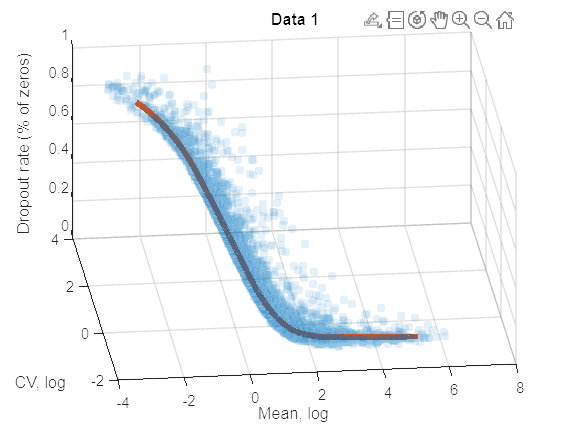

title('Data 1')
view([-6.39 36.70])

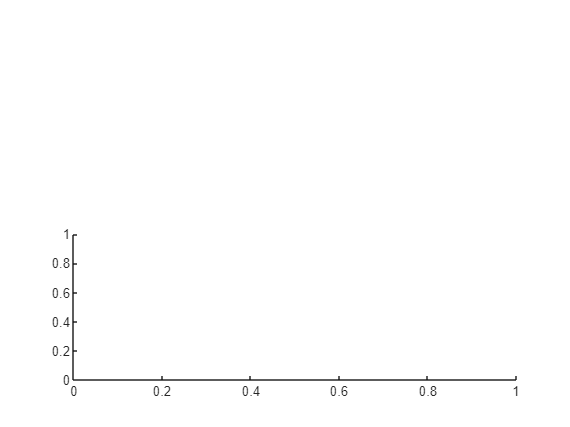


% Show 3D scatter plot and spline-fit curve for Y
%figure;
subplot(2,1,2)

gui.sc_scatter3genes(Y,genelisty,dofit,showdata);

NOTE: Genes with dropout rate > 0.95 are excluded.
scGEAToolbox controls for the variance-mean relationship of gene
expression. scGEAToolbox considers three sample statistics of each
gene: expression mean⁠, coefficient of variation⁠, and dropout rate⁠.
After normalization, it fits a spline function based on piece-wise
polynomials to model the relationship among the three statistics, 
and calculates the distance between each geneis observed statistics
to the fitted 3D spline surface. Genes with larger distances are 
ranked higher for feature selection.


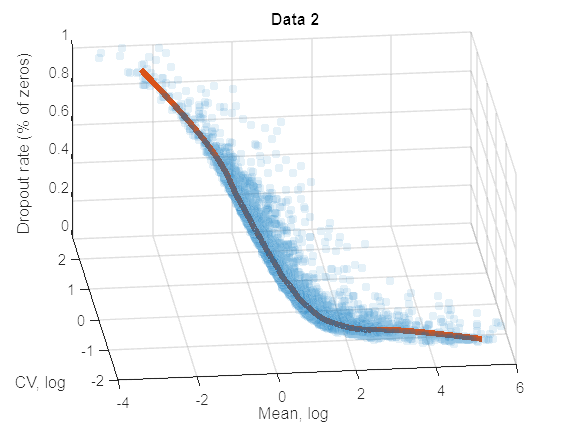

title('Data 2')
% view([24.08 32.68])
view([-6.39 36.70])

## Using function SC_SPLINEFIT2 to fit X and Y separately and obtain DD

value for each gene.

[T2]=sc_splinefit2(X,Y,genelistx,genelisty,true);

NOTE: Genes with dropout rate > 0.95 are excluded.
NOTE: Genes with dropout rate > 0.95 are excluded.


## Top 10 genes with highest DD value.

T2.genes(1:10)

ans = 10×1 string array
    "SAT1"
    "NUPR1"
    "TSLP"
    "CSTB"
    "WFDC2"
    "S100P"
    "H1F0"
    "G0S2"
    "DDIT3"
    "DKK1"


## The End